# 'vector' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'vector.pov', 'image_file', 'vector.png');
    pl.include("glass");

    % Camera
    pl.camera('angle', 50, 'location', [7 11 8.2] / 1.3, 'look_at', [0 0 1], 'type', 'perspective');
    
    % Lights
    % Point
    %pl.light('location', [2 2 20], 'color', [10 10 10], 'shadowless', true);
    pl.light('location', [2 2 20], 'color', [7 7 7], 'shadowless', true);
    
    % Spotlights
    % pl.light('type', 'spotlight', 'location', [0 2 6],    'point_at', [0 0 1], 'color', [1 1 1], 'shadowless', false);
    pl.light('type', 'spotlight', 'location', [7 11 8.2], 'point_at', [0 0 3], 'color', [2 2 2], 'shadowless', true);
    
    % Axis
    % pl.axis('length', [4 4 4], 'radius', 0.04);
   
    % Textures
    finish = "phong 1 reflection {0.02 metallic 0.8}";
    tex_floor  = pl.declare("tex_floor", pl.texture('pigment_odd', [0.01 0.01 0.01], 'pigment_even', [0.02 0.02 0.02], 'finish', finish));
    tex_point = pl.declare("tex_point",  pl.texture('pigment', [0.5 0.5 0.5], 'finish', finish));

    tex_gray   = pl.declare("tex_gray",   pl.texture('pigment', [0.1 0.1 0.1] * 5, 'finish', finish));
    tex_green  = pl.declare("tex_green",  pl.texture('pigment', [0.0 0.3 0.0], 'finish', finish));
    tex_blue   = pl.declare("tex_blue",   pl.texture('pigment', [0.0 0.1 0.3], 'finish', finish));    
    tex_yellow = pl.declare("tex_yellow", pl.texture('pigment', [0.3 0.3 0.0] * 5, 'finish', finish));
    tex_pink   = pl.declare("tex_pink",   pl.texture('pigment', [0.8 0.2 0.3] * 5, 'finish', finish));

    % Floor
    pl.plane('normal', [0,0,1], 'texture', tex_floor);

    % Ponits
    pl.sphere('position', [0  0 0], 'radius', 0.1, 'texture', tex_point);
    pl.sphere('position', [3  2 4], 'radius', 0.07, 'texture', tex_point);
    pl.sphere('position', [-3 2 2], 'radius', 0.07, 'texture', tex_point);

    % Vectors
    pl.vector('p1', [0,0,0], 'p2', [3  2 4], 'tex_odd', tex_pink,   'tex_even', tex_gray, 'radius', 0.04);
    pl.vector('p1', [0,0,0], 'p2', [-3 2 2], 'tex_odd', tex_blue,   'tex_even', tex_gray, 'radius', 0.04);
    pl.vector('p1', [3 2 4], 'p2', [-3 2 2], 'tex_odd', tex_yellow, 'tex_even', tex_gray, 'radius', 0.04);

    % Triangle
    pl.triangle('p1', [0 0 0], 'p2', [3  2 4],  'p3', [-3 2 2], 'texture', 'T_Winebottle_Glass');

pl.scene_end();

#### Render and display

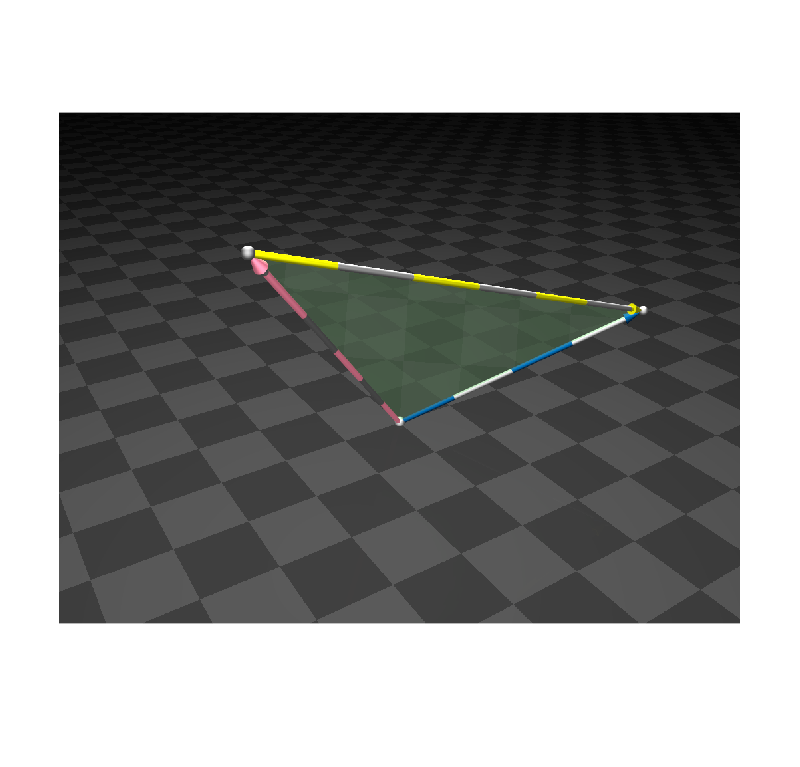

image = pl.render();
imshow(image);

#### Elapsed time


toc

Elapsed time is 2.815265 seconds.
